% Graphs

% Columns are [Time (s)	Main Avg Current (mA)	Main Avg Power (mW)	
% Main Avg Voltage (V)	Main Min Power (mW)]

% Folder path
folder = 'H:\My Drive\UMA\Projects\Seizure detection\Device Power Data - New 1'; 

% Get list of CSV files
files = dir(fullfile(folder,'*.csv'));
file_names = {files.name}

file_names = 1×24 cell array
    {'Nano CPU Run1.csv'}    {'Nano CPU Run2.csv'}    {'Nano CPU Run3.csv'}    {'Nano CPU Run4.csv'}    {'Nano GPU Run1.csv'}    {'Nano GPU Run2.csv'}    {'Nano GPU Run3.csv'}    {'Nano GPU Run4.csv'}    {'Nano Idle 1.csv'}    {'Nano Idle 2.csv'}    {'Nano Transfer Compressed 1_ROI.csv'}    {'Nano Transfer Compressed 2_ROI.csv'}    {'Nano Transfer Original 1_ROI.csv'}    {'Nano Transfer Original 2_ROI.csv'}    {'RasPi CPU Run 1.csv'}    {'RasPi CPU Run 2.csv'}    {'RasPi CPU Run 3.csv'}    {'RasPi CPU Run 4.csv'}    {'RasPi Idle 1.csv'}    {'RasPi Idle 2.csv'}    {'RasPi Transfer Compressed 1_ROI.csv'}    {'RasPi Transfer Compressed 2_ROI.csv'}    {'RasPi Transfer Original 1_ROI.csv'}    {'RasPi Transfer Original 2_ROI.csv'}


warning_state = warning('off', 'all');
data = cell(size(file_names));
for i = 1:length(file_names)
    data{i} = readtable(file_names{i});
end
disp("storing data is successful");

storing data is successful


%%%%%%%%%%%%%%% JETSON NANO %%%%%%%%%%%%%%%

% consumed energy for inference of VAE on CPU166.92
for i = 1:4
    time = data{i}.Time_s_;
    power = data{i}.MainAvgPower_mW_/1000;
    consumed_energy = calcenergy(time, power, time(1), time(end));
    fprintf('Nano CPU Run %d = %f J | time: %f\n', i, consumed_energy, max(time));
end

Nano CPU Run 1 = 380.093016 J | time: 90.859600
Nano CPU Run 2 = 364.627711 J | time: 86.923000
Nano CPU Run 3 = 393.710642 J | time: 96.593400
Nano CPU Run 4 = 386.931367 J | time: 94.169800


% consumed energy for inference of VAE on GPU
for i = 5:8
    time = data{i}.Time_s_;
    power = data{i}.MainAvgPower_mW_/1000;
    idl_pw = data{9}.MainAvgPower_mW_/1000;
    idx = size(time);
    power = power - idl_pw(1:idx(1));
    consumed_energy = calcenergy(time, power, time(1), time(end));
    fprintf('Nano GPU Run %d = %f J | time: %f\n', i, consumed_energy, max(time));
end

Nano GPU Run 5 = 19.995411 J | time: 14.873200
Nano GPU Run 6 = 9.666931 J | time: 9.460000
Nano GPU Run 7 = 22.087895 J | time: 16.748600
Nano GPU Run 8 = 26.526069 J | time: 19.556200


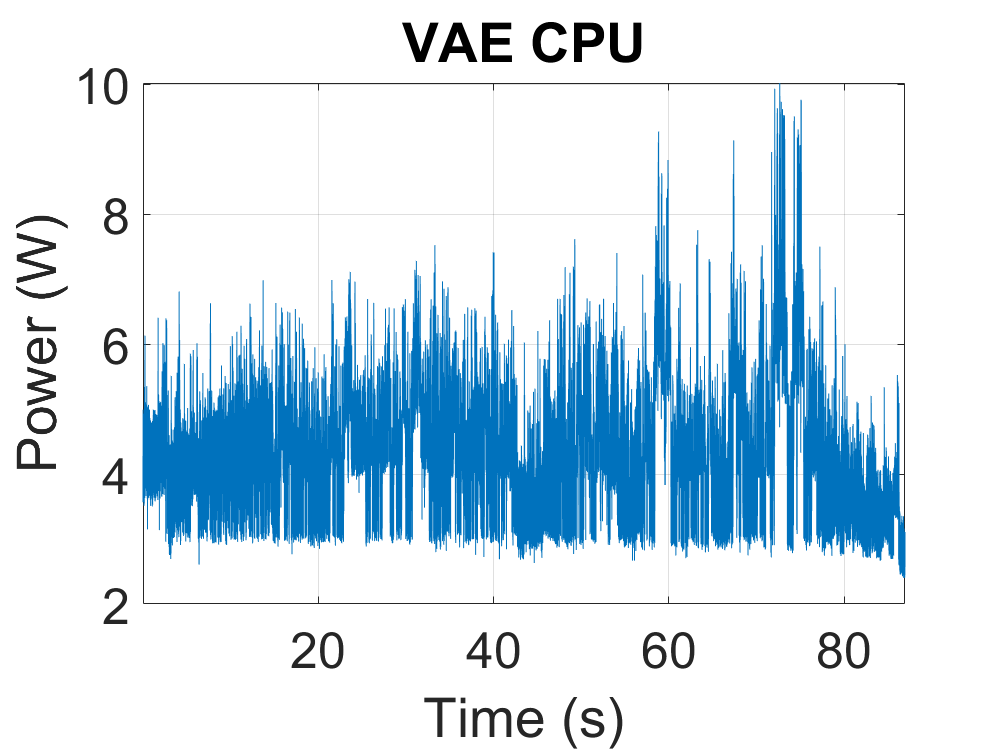

% Power VAE CPU Jetson
fig = figure;
time = data{2}.Time_s_; power = data{2}.MainAvgPower_mW_/1000;
fig.Position = [100 100 800 600];
plot(time, power);
grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('VAE CPU')
xlim([time(1) max(time)])

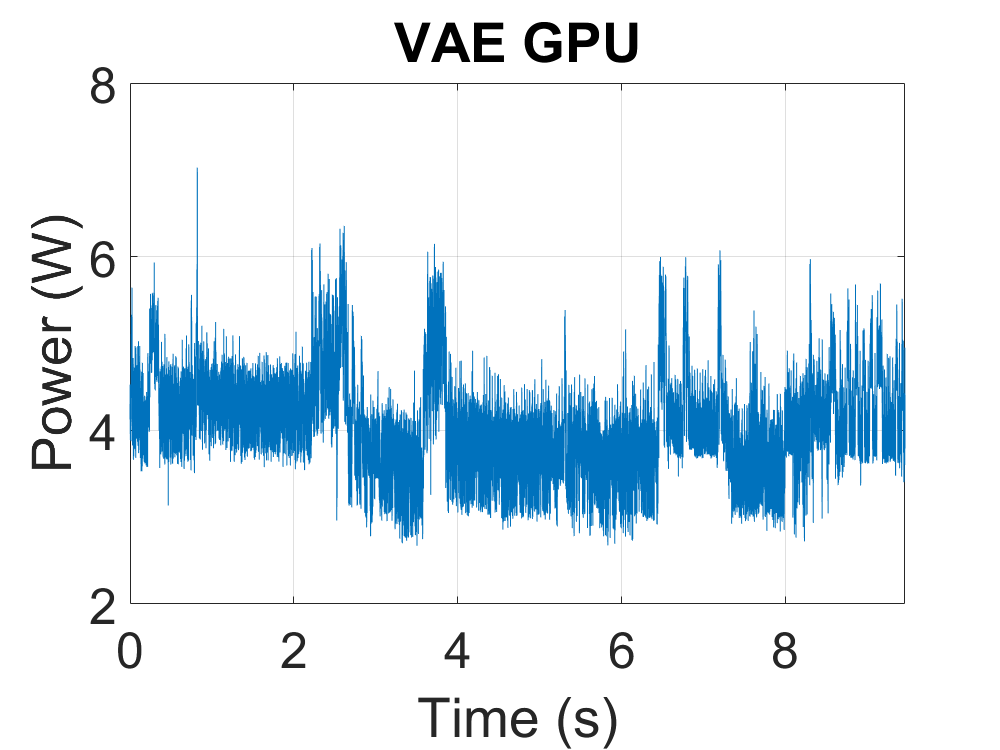

% Power VAE GPU Jetson
fig = figure;
time = data{6}.Time_s_; power = data{6}.MainAvgPower_mW_/1000;
fig.Position = [100 100 800 600];
plot(time, power);
grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('VAE GPU')
xlim([time(1) max(time)])

% consumed energy for transfer compressed and original Jetson
for i = 11:14
    time = data{i}.Time_ms_/1000;
    time = time - min(time);
    power = data{i}.MainAvgPower_mW_/1000;
    consumed_energy = calcenergy(time, power, time(1), time(end));
    fprintf('Nano transfer %d = %f J | time: %f\n', i, consumed_energy, max(time));
end

Nano transfer 11 = 303.086144 J | time: 86.174000
Nano transfer 12 = 282.564399 J | time: 81.002400
Nano transfer 13 = 390.323646 J | time: 100.417400
Nano transfer 14 = 399.482844 J | time: 101.111600


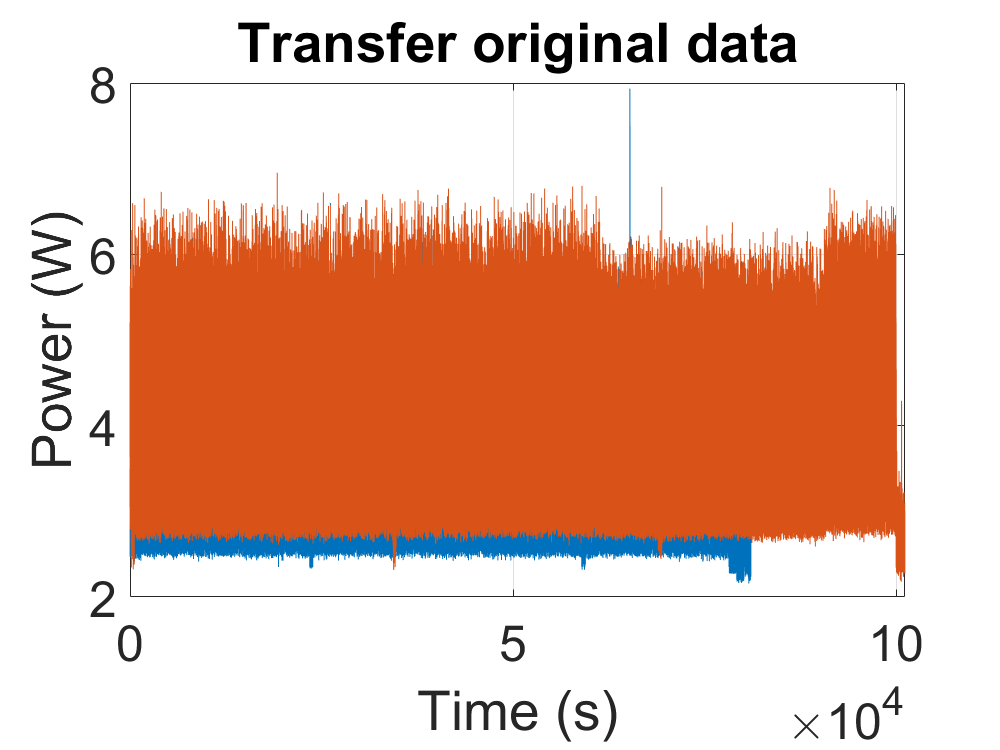

1

% Power transfer compressed Jetson
fig = figure;
time = data{12}.Time_ms_; time = time - min(time);
power = data{12}.MainAvgPower_mW_/1000;
power_comp = power;
fig.Position = [100 100 800 600];
plot(time, power);
grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('Transfer Compressed data')
xlim([time(1) max(time)])
% Power transfer original Jetson
hold on
time = data{14}.Time_ms_; time = time - min(time);
power = data{14}.MainAvgPower_mW_/1000;
power_orignial = power;
fig.Position = [100 100 800 600];
plot(time, power);
grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('Transfer original data')
xlim([time(1) max(time)])

%%%%%%%%%%%%%%% RASPBERRY PI %%%%%%%%%%%%%%%

% consumed energy for inference of VAE on CPU
for i = 15:18
    time = data{i}.Time_s_;
    power = data{i}.MainAvgPower_mW_/1000;
    consumed_energy = calcenergy(time, power, time(1), time(end));
    fprintf('Nano CPU Run %d = %f J | time: %f\n', i, consumed_energy, max(time));
end

Nano CPU Run 15 = 74.215086 J | time: 20.261200
Nano CPU Run 16 = 71.590007 J | time: 19.461400
Nano CPU Run 17 = 69.607675 J | time: 18.967000
Nano CPU Run 18 = 68.892870 J | time: 18.728800


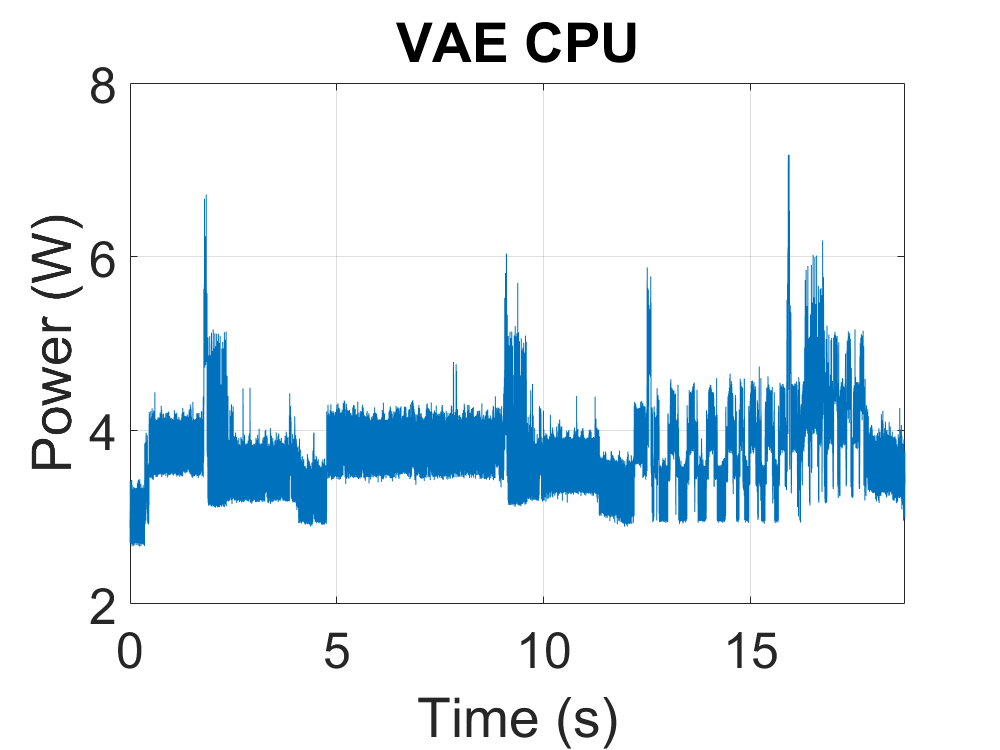


% Power VAE CPU RASPI
fig = figure;
time = data{18}.Time_s_; power = data{18}.MainAvgPower_mW_/1000;
fig.Position = [100 100 800 600];
plot(time, power);
grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('VAE CPU')
xlim([time(1) max(time)])

% Power VAE GPU Jetson
fig = figure;
time = data{6}.Time_s_; power = data{6}.MainAvgPower_mW_/1000;
fig.Position = [100 100 800 600];
plot(time, power);
grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('VAE GPU')
xlim([time(1) max(time)])

% consumed energy for transfer compressed and original Jetson
for i = 21:24
    time = data{i}.Time_ms_/1000;
    time = time - min(time);
    power = data{i}.MainAvgPower_mW_/1000;
    consumed_energy = calcenergy(time, power, time(1), time(end));
    fprintf('Nano transfer %d = %f J | time: %f\n', i, consumed_energy, max(time));
end

Nano transfer 21 = 163.897924 J | time: 43.429000
Nano transfer 22 = 140.706638 J | time: 38.546000
Nano transfer 23 = 243.918801 J | time: 60.928200
Nano transfer 24 = 171.092313 J | time: 45.133200


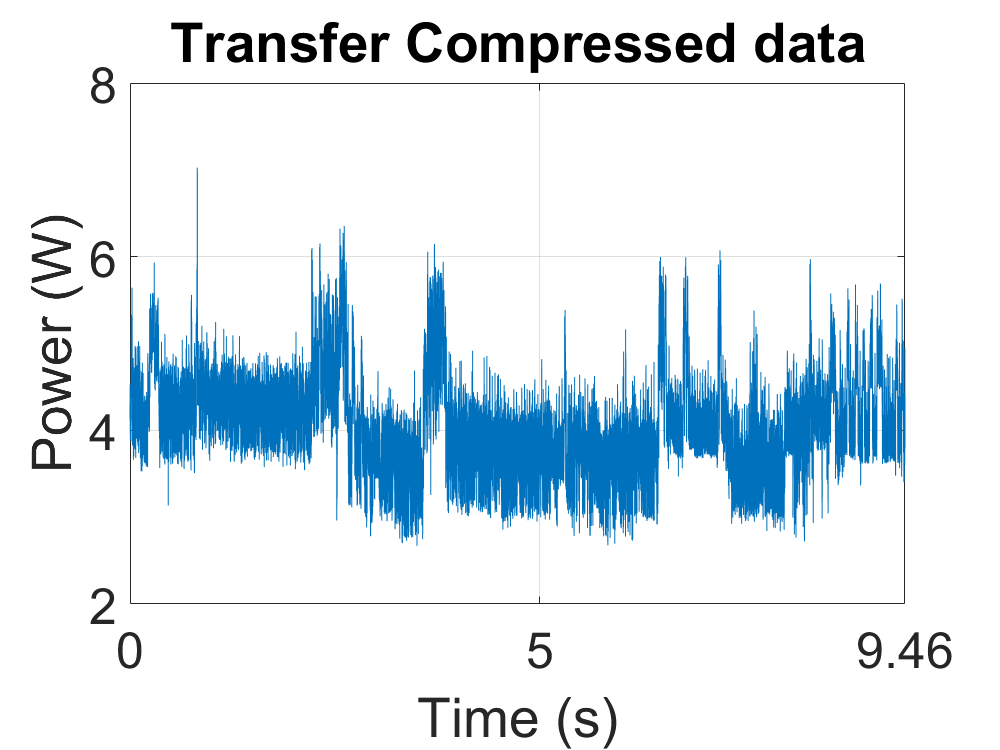



% Power transfer compressed Jetson
fig = figure;
time = data{6}.Time_s_; time = time - min(time);
power = data{6}.MainAvgPower_mW_/1000;
fig.Position = [100 100 800 600];
plot(time, power);
grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('Transfer Compressed data')
xlim([time(1) max(time)])
xticks([time(1):5:max(time) max(time)])

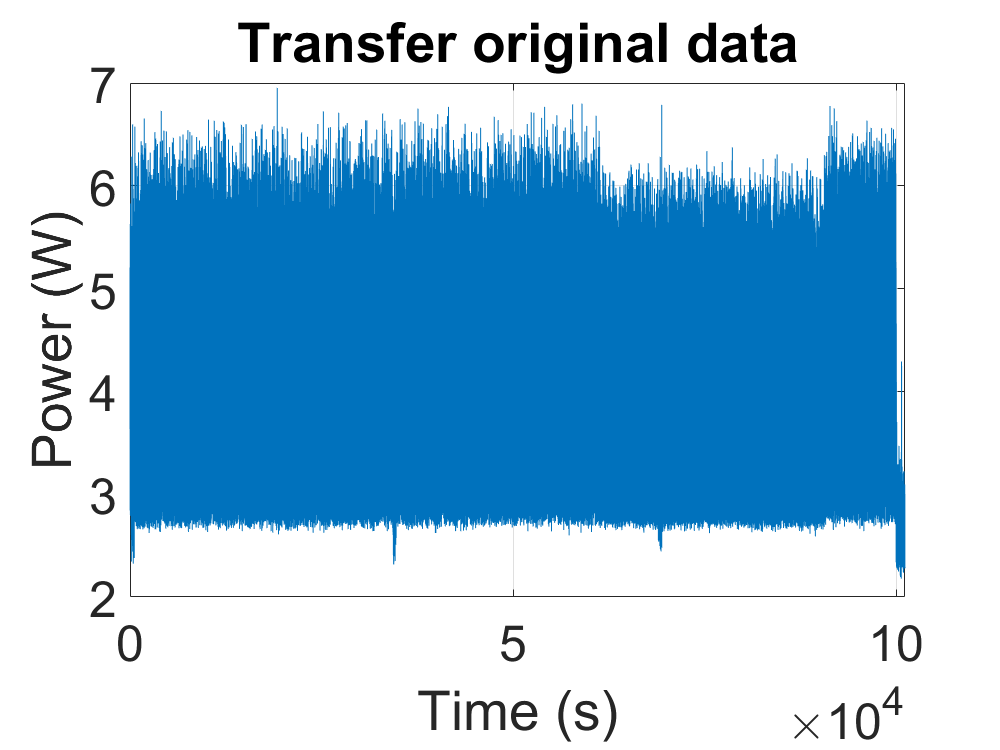

% Power transfer original Jetson
fig = figure;
time = data{14}.Time_ms_; time = time - min(time);
power = data{14}.MainAvgPower_mW_/1000;
fig.Position = [100 100 800 600];
plot(time, power);
grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('Transfer original data')
xlim([time(1) max(time)])

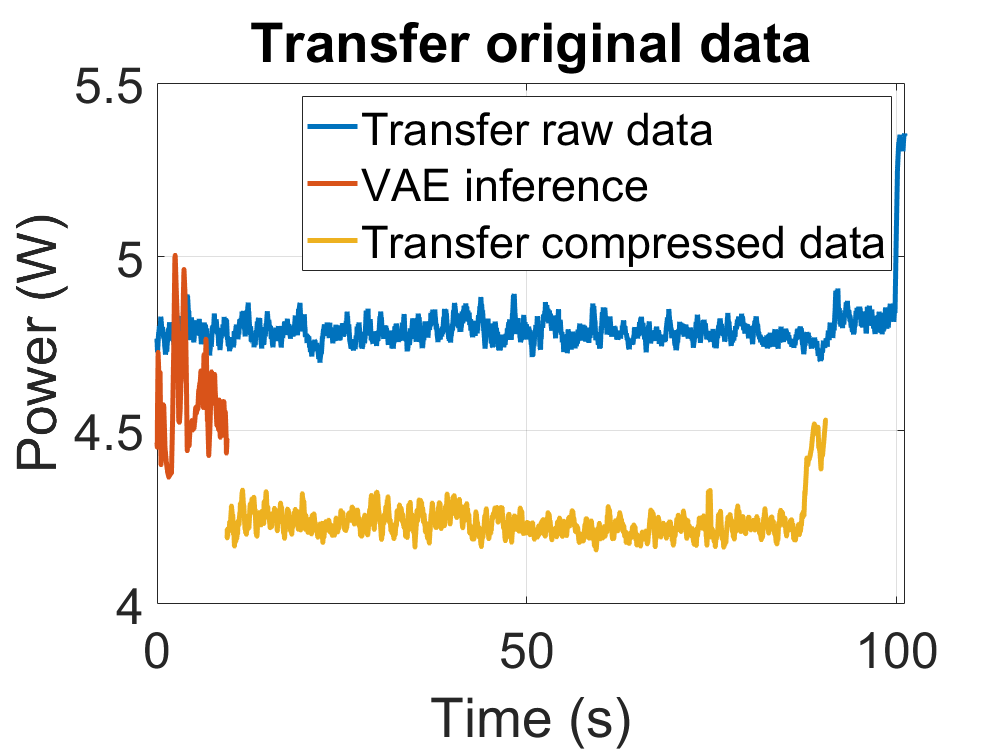

% NANO compressed transfer vs original transfer

fig = figure;

% transferring original 
time = data{14}.Time_ms_/1000; time = time - min(time);
power = data{14}.MainAvgPower_mW_/1000; 
fig.Position = [100 100 800 600];
y = envelope(power,2000,'rms');
plot(time, y, 'LineWidth',3);
xlim([time(1) max(time)])

% transfer compressed
hold on
time1 = data{6}.Time_s_; time1 = time1 - min(time1);
power1 = data{6}.MainAvgPower_mW_/1000;
y = envelope(power1,2000,'rms');
plot(time1, y, 'LineWidth',3);

time = data{12}.Time_ms_/1000; time = time - min(time);
power = data{12}.MainAvgPower_mW_/1000; 
fig.Position = [100 100 800 600];
% plot(time, power);
y = envelope(power,2000,'rms');
plot(time+max(time1), y, 'LineWidth',3);

grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('Transfer original data')
legend("Transfer raw data","VAE inference","Transfer compressed data")

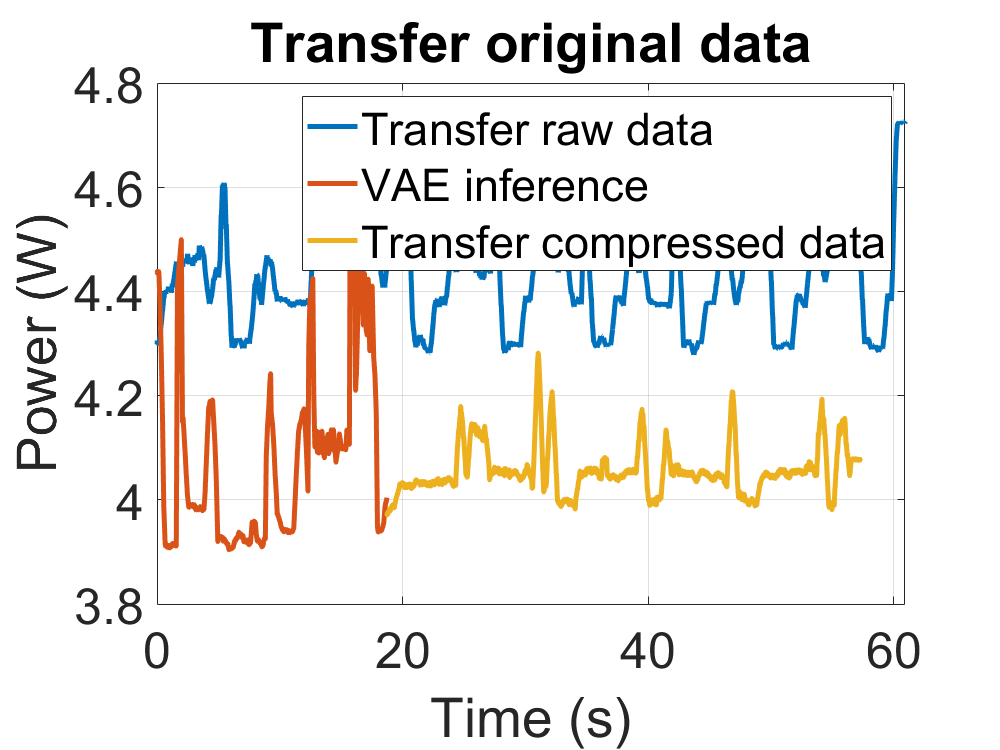

% Raspi compressed transfer vs original transfer

fig = figure;

% transferring original 
time = data{23}.Time_ms_/1000; time = time - min(time);
power = data{23}.MainAvgPower_mW_/1000; 
fig.Position = [100 100 800 600];
y = envelope(power,2000,'rms');
plot(time, y, 'LineWidth',3);
xlim([time(1) max(time)])

% transfer compressed
hold on
time1 = data{18}.Time_s_; time1 = time1 - min(time1);
power1 = data{18}.MainAvgPower_mW_/1000;
y = envelope(power1,2000,'rms');
plot(time1, y, 'LineWidth',3);

time = data{22}.Time_ms_/1000; time = time - min(time);
power = data{22}.MainAvgPower_mW_/1000; 
fig.Position = [100 100 800 600];
y = envelope(power,2000,'rms');
plot(time+max(time1), y, 'LineWidth',3);

grid on
set(gca,'fontsize',30) % Set font size to 16
xlabel('Time (s)')
ylabel('Power (W)')
title('Transfer original data')
legend("Transfer raw data","VAE inference","Transfer compressed data")